# placeholder

## load in data

% double click on the .mat file you wish to run through this pipeline or
% use load method
filename = 'ADT_2021-09-30_eegONLY.mat'; % change this file name for every case


## visualizing pre-processing

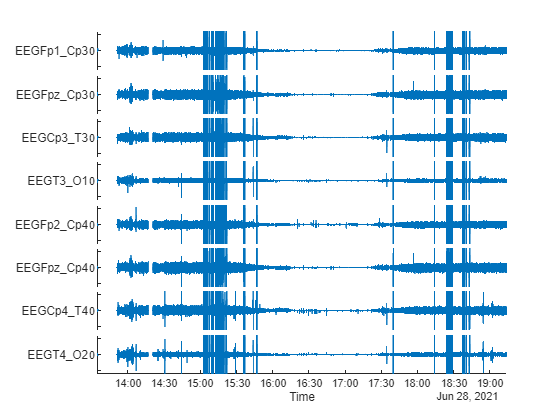

stackedplot(allEDFs.data{'EEG'})

## preproccesing steps

allEDFs_filtered = preprocess_EEG(allEDFs);
% TODO: save output to new struc

## determination of baseline indices and baseline window

[window_postintubation_baseline, intubation_index, incision_index] = baseline_3D(allEDFs_filtered);

## EEG analysis

[P_baseline, P_analysis, GMModel, alert_count] = analysis_EEG(allEDFs_filtered, incision_index, window_postintubation_baseline);

There was an eror fitting the GMM
regularize data and try againno EEG alerts found after baseline

## SSEP analysis